u = 1; %force
b = 0.1 %damping constant

b = 0.1000

k = 0.4 %spring constant

k = 0.4000

m = 2 %mass

m = 2

dt = 0.02; %timestep
position  = 0;
velocity  = 0;
acceleration  = 0;

%calculating second-order system characteristics and settling time
natural_freq = sqrt(k/m)

natural_freq = 0.4472

damping_ratio = b/(2*sqrt(m*k))

damping_ratio = 0.0559

settle_time = 4/(natural_freq * damping_ratio)

settle_time = 160



%preparing data collection
time = 0:dt:settle_time;
y_values = zeros(1, length(time))

y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


overshoot = zeros(1, length(time))

overshoot =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


index = 1:1:length(time)

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



%equilibrium position
equil_pos = u/k

equil_pos = 2.5000


for num = index
    y_values(num) = position;

    acceleration = (u - (b*velocity) - (k*position))/m;
    
    velocity = velocity + acceleration * dt;
    position = position + velocity * dt;

    %finding and documenting peaks
    if num > 2
        if y_values(num-1) > y_values(num-2) && y_values(num-1) > position
            calc = ((y_values(num-1) - (equil_pos)) / (equil_pos)) * 100;
            overshoot(num) = calc;
        end
    end    

    y_values(num) = position;

end

%plotting
plot(time,y_values, "r")

hold on

overshoot

overshoot =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


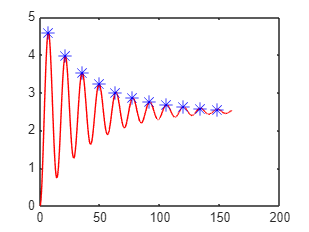


peak_indices = find(overshoot ~= 0);

plot(time(peak_indices), y_values(peak_indices), 'b*', 'MarkerSize', 10)